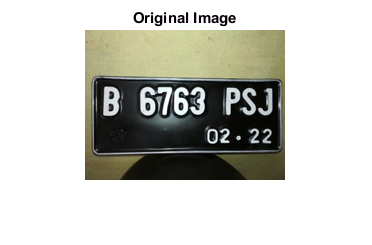

clc;
clear;
close all;

%original dan resized
I = imread('Plat\Plat.jpg');
I = imresize(I, [NaN 200]);
figure, imshow(I), title('Original Image');

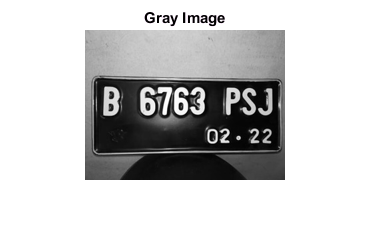


%grayscale
G = rgb2gray(I);
figure, imshow(G), title('Gray Image');

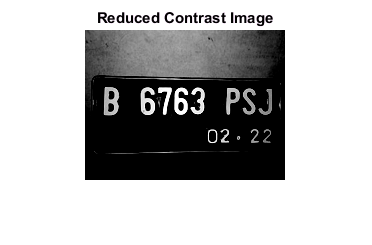


%adjust contrast
G = imadjust(G, [.55 1], []);
G = imadjust(G);
figure, imshow(G), title('Reduced Contrast Image');

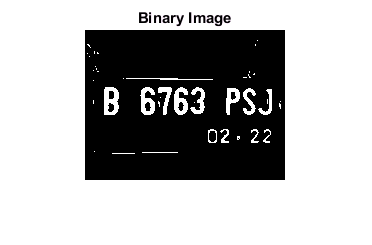


%binerisasi
blocksize = [100 100];
fungsi = @(block_struct) im2bw(block_struct.data, graythresh(block_struct.data));
BW = blockproc(G, blocksize, fungsi);
BW = imclearborder(BW);
figure, imshow(BW), title('Binary Image');

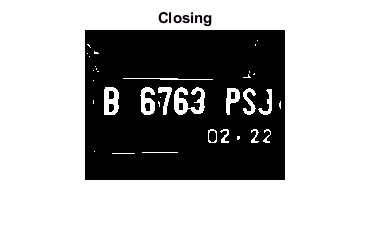


%closing
BWd = bwmorph(BW, 'close', 5);
figure, imshow(BWd), title('Closing');

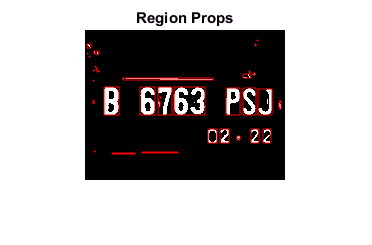


%regionprops
BWr = regionprops(BWd, 'BoundingBox', 'Area', 'Image');
figure, imshow(BW), title('Region Props');
hold on;
pixelT = [];
for i=1:size(BWr,1)
    rectangle('Position', BWr(i).BoundingBox,'edgecolor','red');
%    pixelT = pixelT + BWr(i).Area;
    pixelT(1,i) = BWr(i).Area;
end

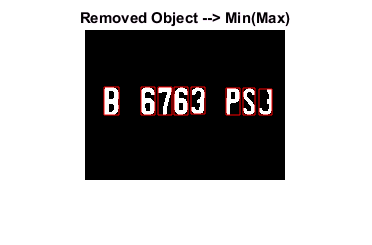


%remove object --> min(max)
arr = sort(pixelT, 'descend');
arrMaxP = arr(1,8);
[c_max, idx_max] = min(arrMaxP);
T = c_max;
cc = bwconncomp(BWd);
removeMask = [BWr.Area]<T;
BWremove2 = BWd;
BWremove2(cat(1, cc.PixelIdxList{removeMask})) = false;
BWremove2 = bwmorph(BWremove2, 'open', Inf);

dir = 'D:\\UNUD TI\\6 - Semester 6\\Machine Learning\\Matlab\\Test_02\\_SegmentedImage\';
S = regionprops(BWremove2, 'BoundingBox', 'Image');
figure, imshow(BWremove2), title('Removed Object --> Min(Max)');
hold on;
for i=1:size(S,1)
    rectangle('Position', S(i).BoundingBox,'edgecolor','red');
    namafile = strcat('objek',int2str(i),'.jpg');
    imwrite(S(i).Image,strcat(dir,namafile),'jpg');
end

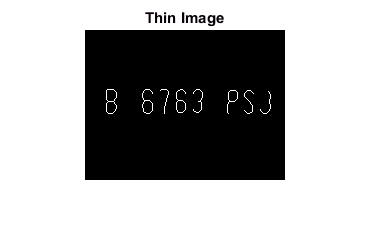


%thinning
BWt = bwmorph(BWremove2, 'thin', Inf);
figure, imshow(BWt), title('Thin Image');